# DEDP Lab 01 - Distributions of random variables. Histograms

## 1. Objective

Gain familiarity with the Matlab environment, and with the functions useful for working with random variables.

## 2. Theoretical aspects     

### 2.1. Random variables in Matlab

#### 2.1.1 The normal distribution

Generate a value according to standard normal distribution (mu=0, sigma^2 = 1):

Run the following line several times and observe the different values obtained.

x = randn()

x = 0.4178

Generate multiple random variables from the standard normal distribution):

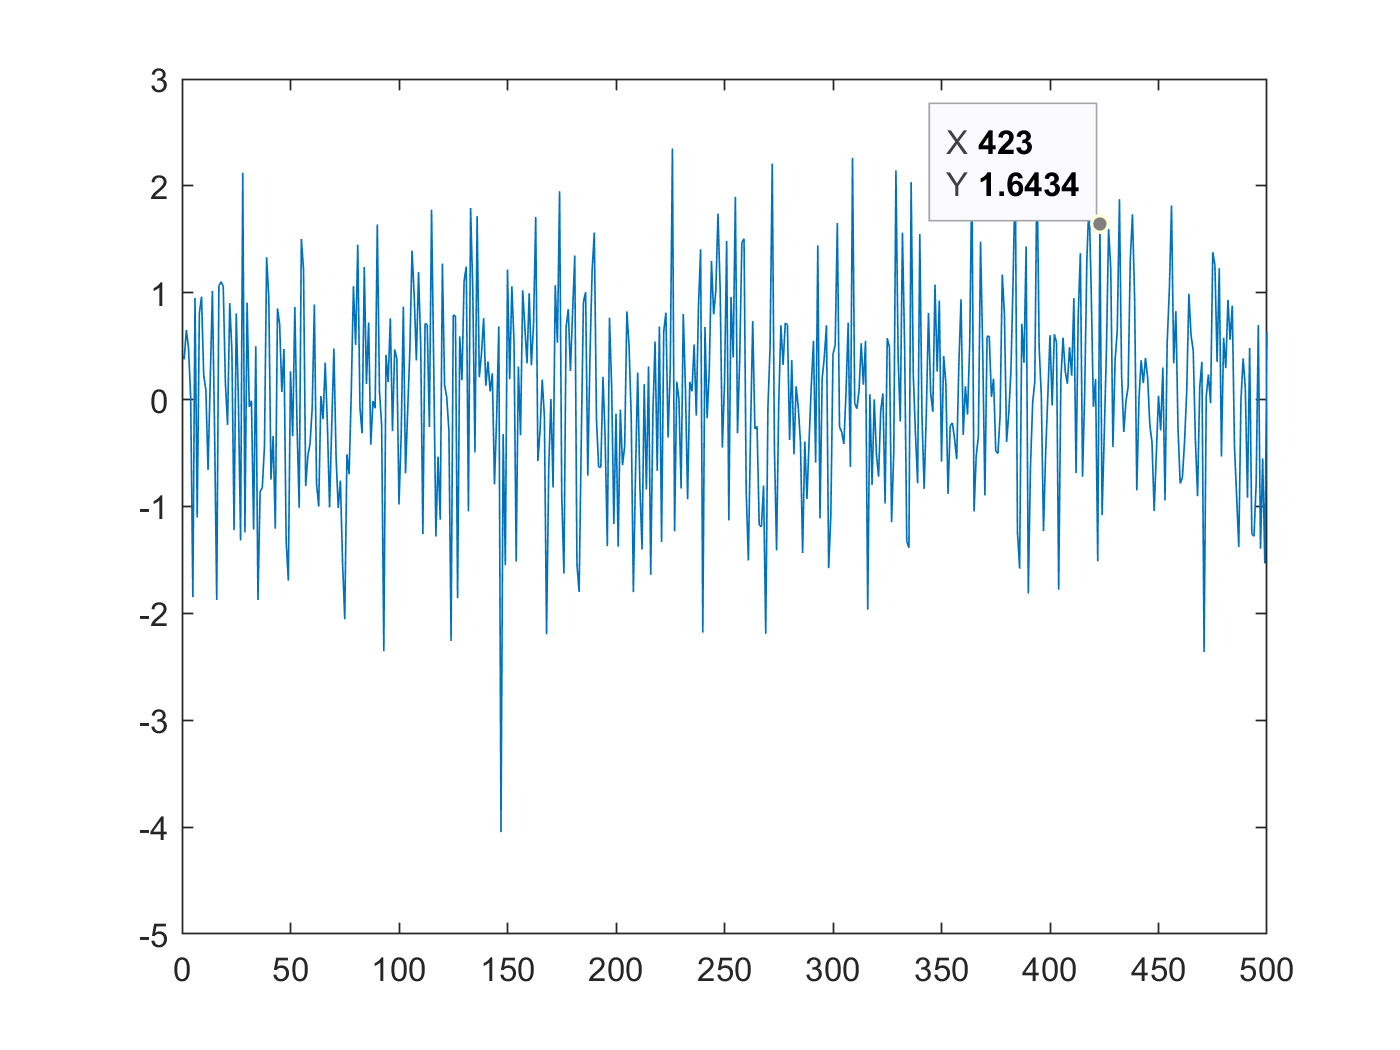

x = randn(1, 500);  % A vector with 50 independent values, 
                    % each one from the standatd normal distribution
plot(x);     % What is the average value of these values?

Use a normal distribution with custom mean value and variance:

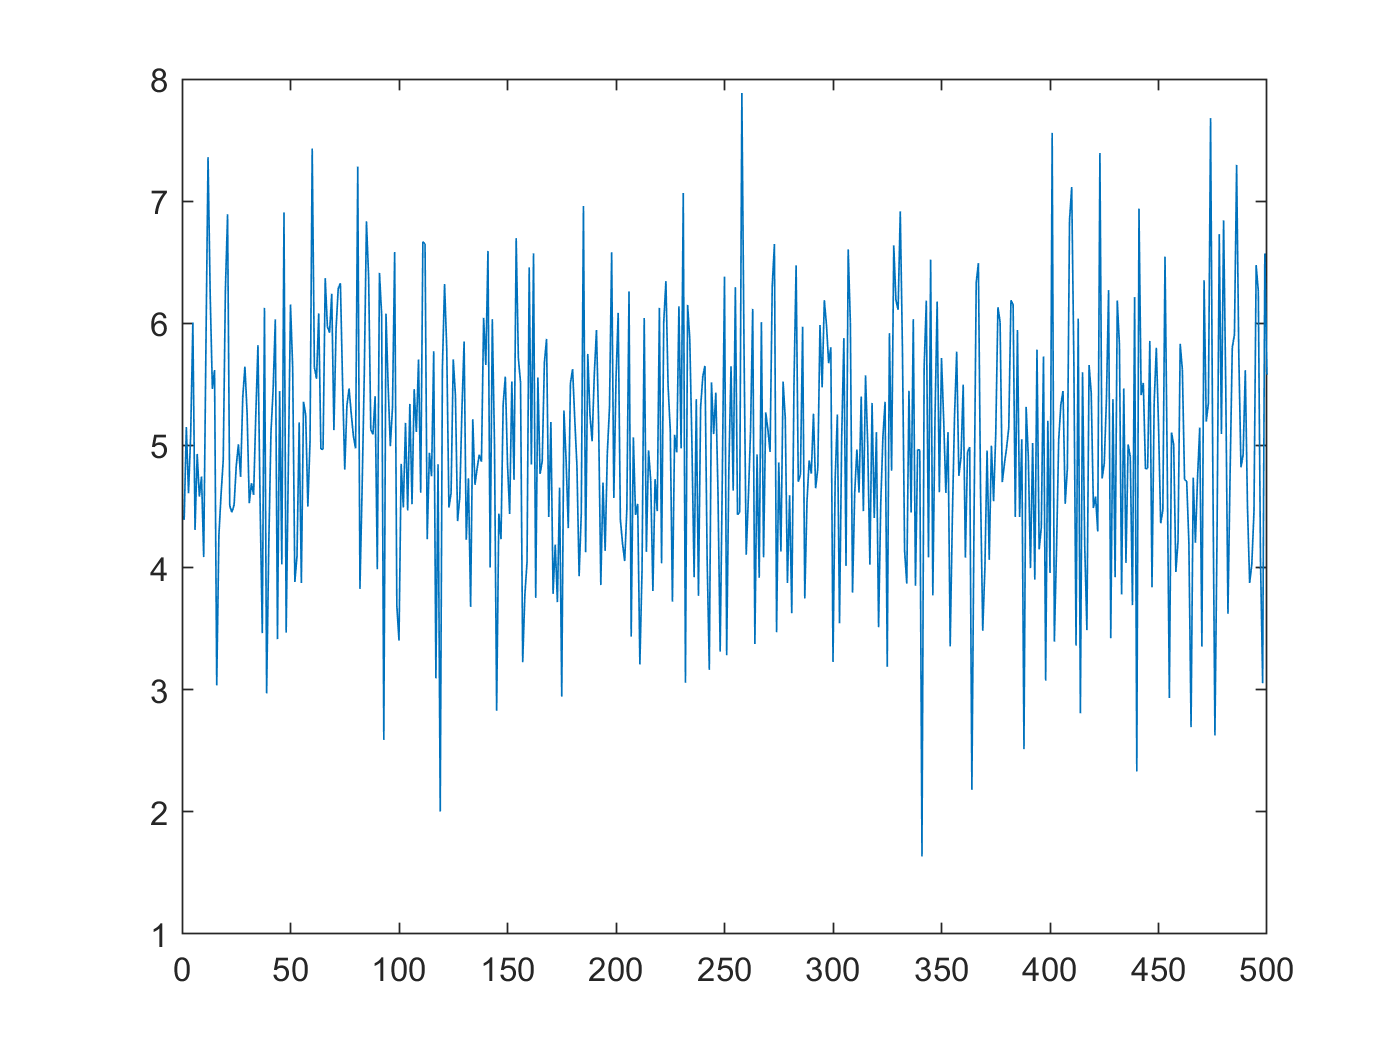

mean = 5;  % mean
var  = 1;  % variance
x2 = mean + sqrt(var)*randn(1,500);
plot(x2);     % What has changed?

#### 2.1.2 The uniform distribution

Generate values uniformly between (0,1):

y  = rand()         % A single value

y = 0.6277

yv = rand(1, 100)   % 100 values arranged in a row vector

yv =     0.5933    0.4828    0.4756    0.5114    0.6199    0.4487    0.7251    0.0415    0.4451    0.7388    0.5263    0.3287    0.1064    0.1050    0.5447    0.7442    0.1380    0.6282    0.0760    0.5632    0.7293    0.4692    0.1163    0.8229    0.0426    0.2920    0.1111    0.1072    0.4044    0.7333    0.3859    0.9675    0.8416    0.9664    0.8456    0.3588    0.4757    0.4613    0.0264    0.0316    0.6344    0.2657    0.4412    0.3937    0.6259    0.6605    0.5750    0.7417    0.6733    0.3291


Generate values uniformly between (a,b):

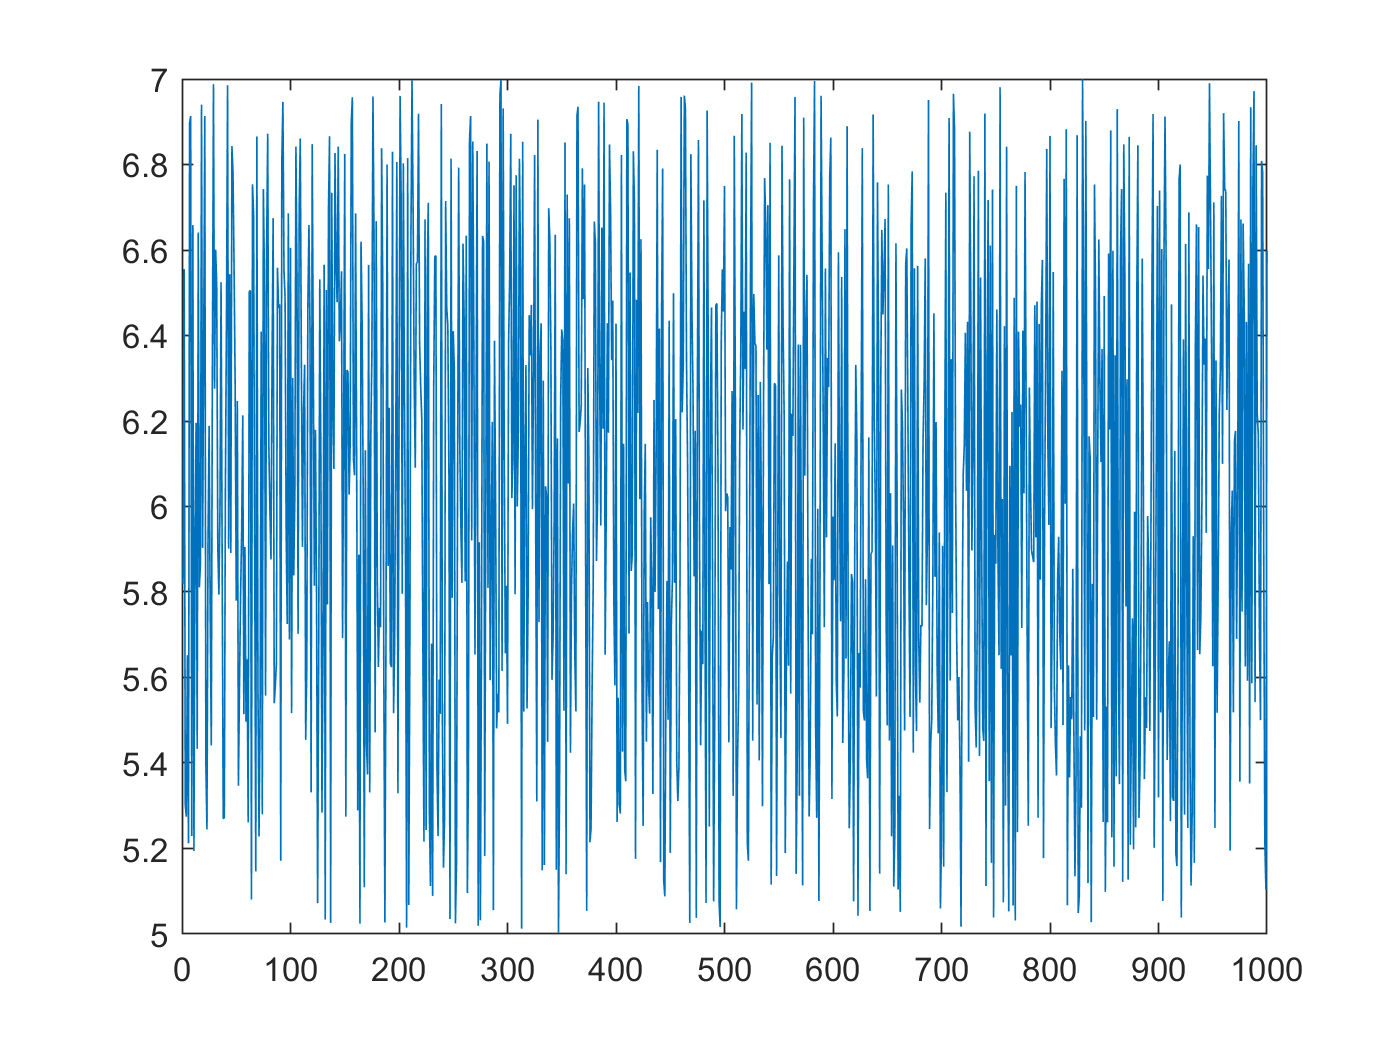

a = 5;
b = 7;
yv2 = a + (b-a)*rand(1, 1000); % 1000 values arranged in a row vector
plot(yv2)           % What is the range of the values>

### 2.2. Functions in Matlab

Functions in Matlab are created in a separate file.

Open a separate file and write the following. Uncomment all the line first.

% function y = my_function(a ,b, c)
% 
% % Do something here
% y = a + b*2 + c^3;
% 
% end

z = 300777

Save the file as **my_function.m**

**Important: **Matlab identifies the function by the name of the file, not by the name written inside.

Call the function from the Command Line as follows (uncomment first):

% Calls the function defined in my_function.m
%rez = my_function(2, 4, 7);   

### 2.3 Histogram plots

Histogram plots illustrate how data is distributed. In matlab they are created with the `hist()` function.

Example:

% Make a vector with zeros, ones, and some values from 2 to 10
a = [zeros(1,30), 4*ones(1,40), 2:0.5:6]   % using concatenation with [ ]

a =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4


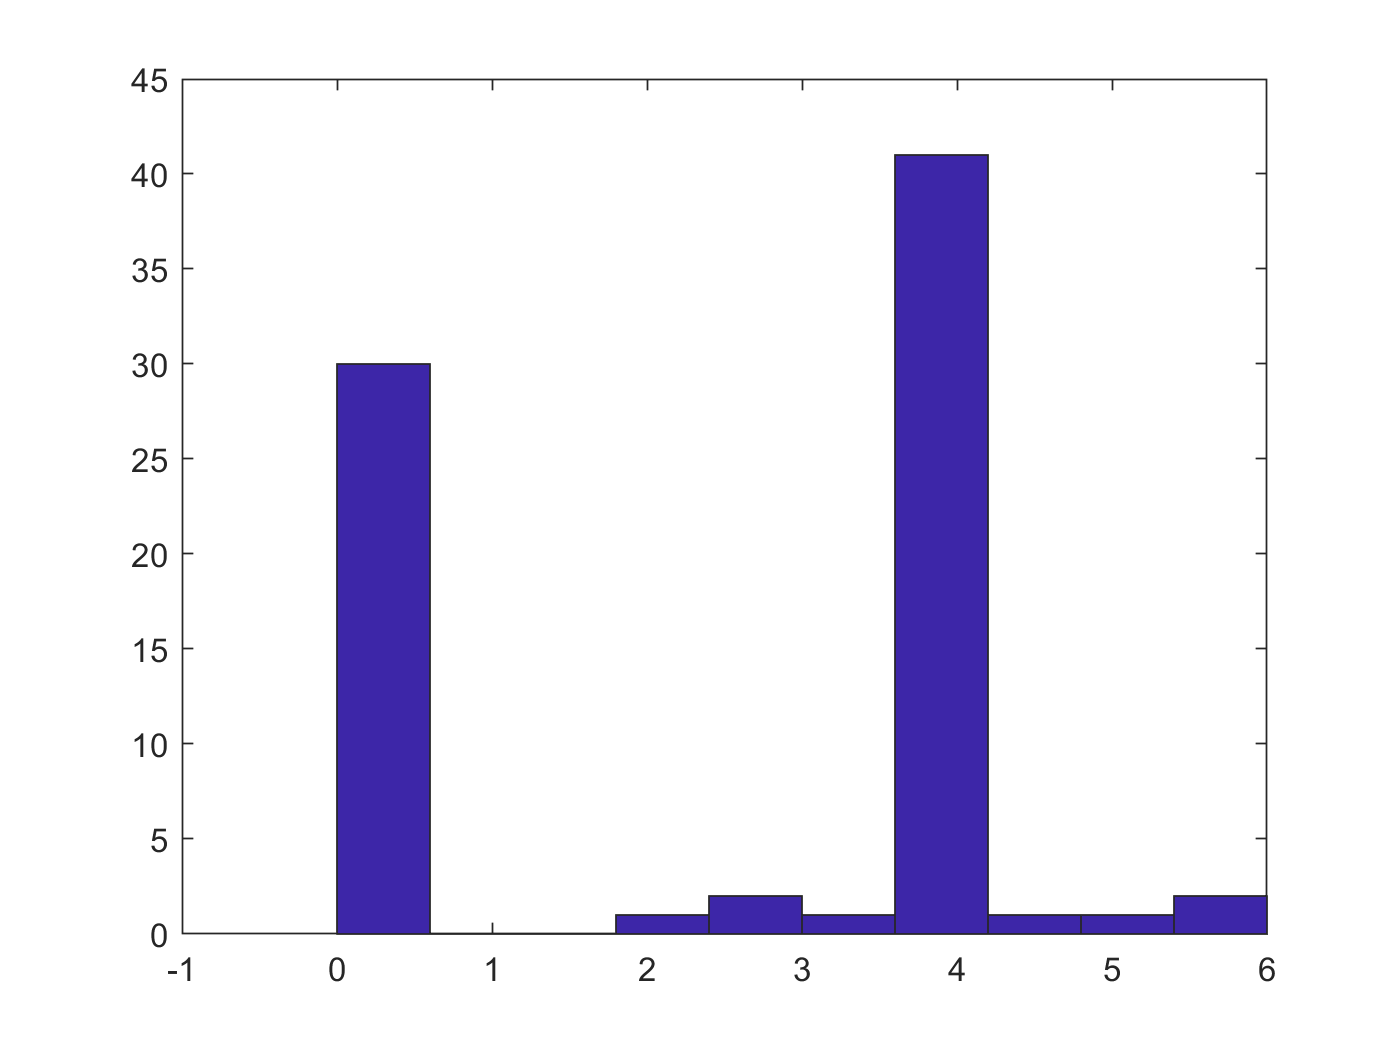

hist(a)

The function splits the value range (0, 6) into 10 bins, and counts how many number fall in each bin, then displays these numbers as a bar graph.

Read the documentation of `hist()` for more details (e.g. chaneg the number of bins).

## 3. Exercises

1. Generate a vector $v1$ with 10000 values from the normal distribution $\mathcal{N}(\mu=2, \sigma^2=2)$ and plot the values.

2. Generate a vector $v2$ with 10000 values from the uniform distribution $\mathcal{U}[-4,10]$ and plot the values

3. Plot the histogram of the data vectors using `hist()`.

4. Create a Matlab function `myPDF()` that estimates the probability density function from a vector of data

- the function requires three arguments and returns one value: `p = myPDF(v,x,epsilon)`

- `v` is a vector, and `x`, `epsilon` and `p` are scalar numbers

- the function computes how many elements from `v` are in the interval $[x - \epsilon, x + \epsilon]$, divided to the total number of elements of `v`, and also divided to 2 times `epsilon`

- Question: given a long sequence `v`, what does the return value `p` mean?

5. Plot the probability density function estimated from a vector of data

- generate a vector `n` of 50 values uniformly spread from -8 to 18

- apply ``myPDF()`` to all values from the vector `n`, with both vectors ``v`` generated above. Use ``epsilon`` = 0.1.

- plot the results of the function against the values from ``n``

## 4. Supplementary Exercises

6. Create a Matlab function ``myCDF()`` that estimates the cumulative distribution function (CDF) from a vector of data

- the function requires two arguments and returns one value: ``p = myCDF(v,x)``

-  `v` is a vector, `x` and `p` are scalar numbers

- the function computes how many elements from `v` are smaller or equal than `x`, divided to the total number of elements of `v`

- question: given a long sequence `v`, what does the return value `p` mean?

7. Use the `myCDF()` function to compute the CDF of the normal / uniform distributions from the two vectors generated previously.

- generate a vector n of 50 values uniformly spread between -8 to 18

- apply `myCDF()` to all values from the vector n, for the two vectors generated previously

- plot the results of the function against the values of n

## 5. Final questions

1. What should we modify in order to get **more accurate** results / plots of these functions?